clc
clear all
close all
pause('off')

# Assignment 2

# Japnit Sethi

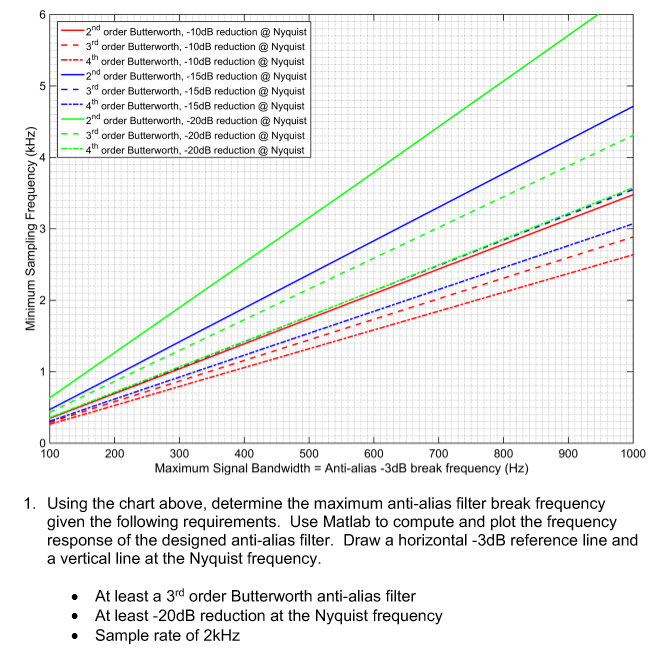

% Problem 1

% Building the Anti Alias Filter
dB_red = -20; % 20 dB reduction
fs = 2e3;     % Hz Sample Rate
N = 3; % 3rd Order

fbreak = 460; % Break frequency from the plot
wbreak = 2*pi*fbreak;

fprintf(' Maximum anti-alias filter break frequency: %3.0f Hz ', fbreak);

 Maximum anti-alias filter break frequency: 460 Hz 

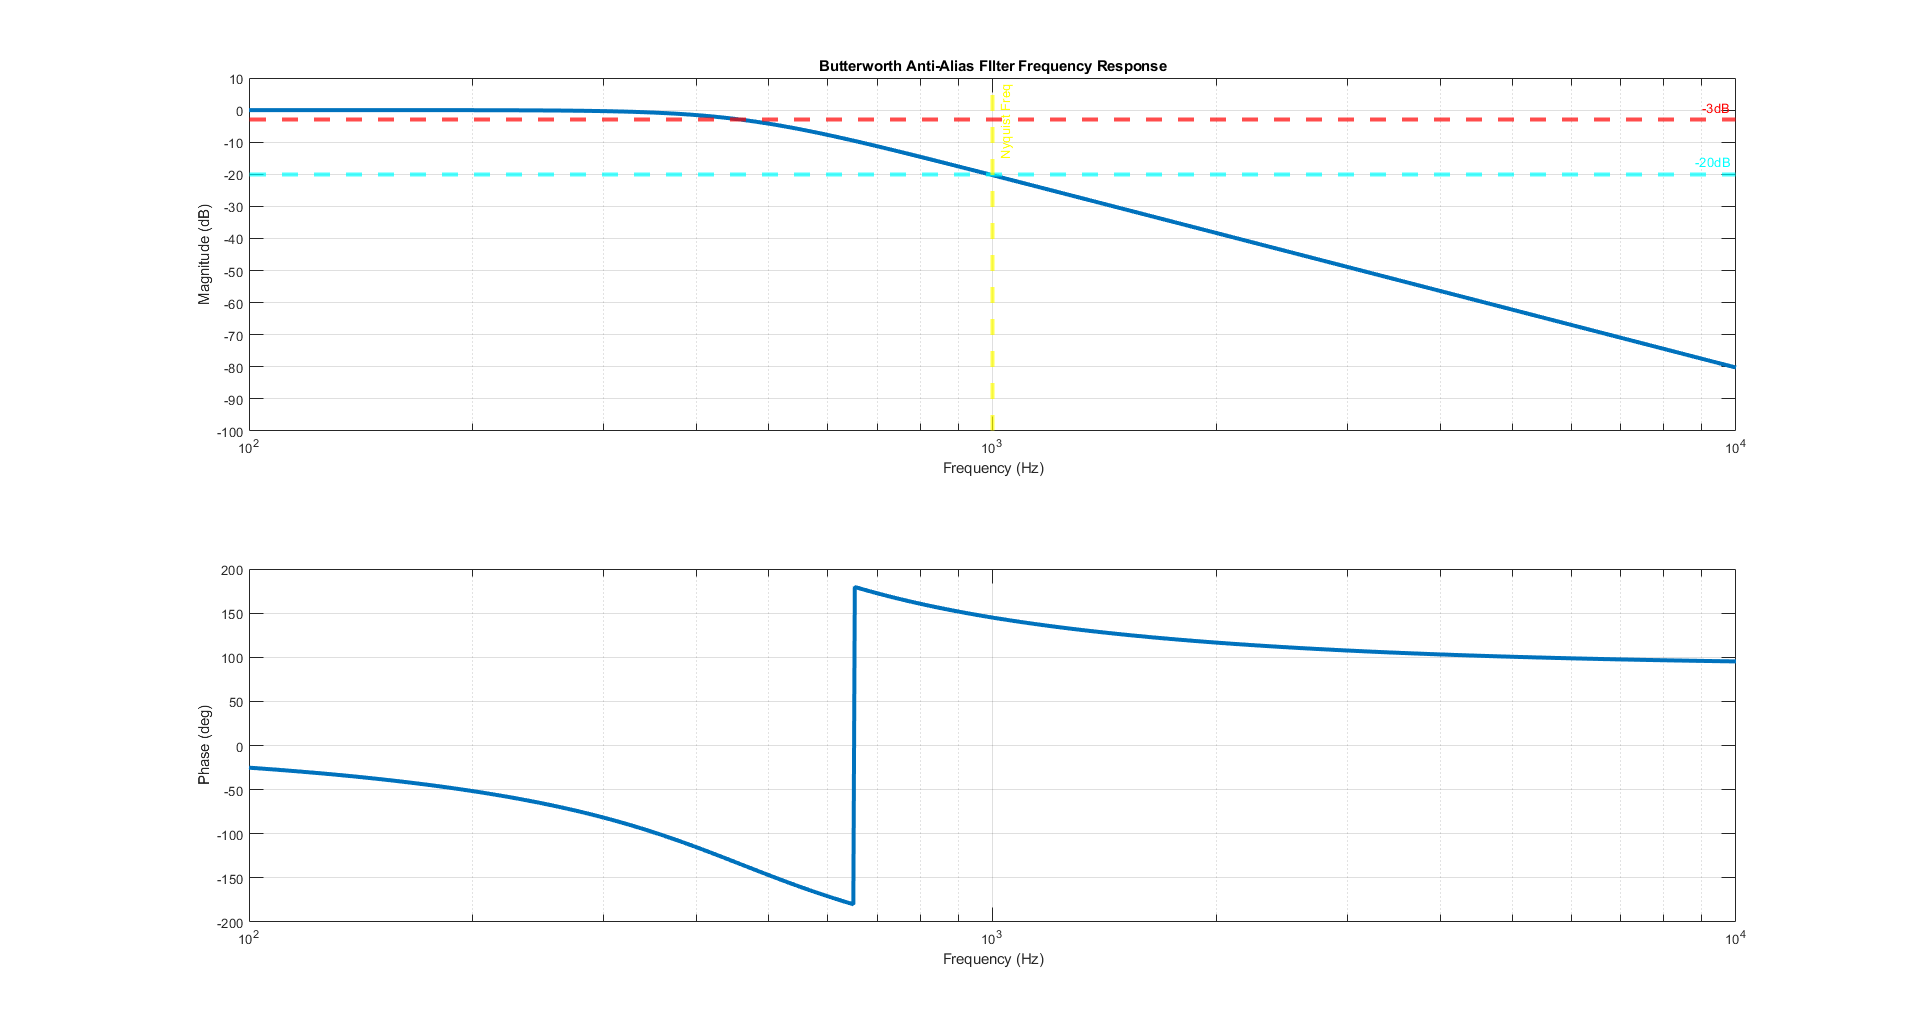


[num, den] = butter(N, wbreak, 's');

fr = logspace(2, 4, 1000);
P1_frf = freqs(num, den, 2*pi*fr);

Magnitude = abs(P1_frf);
Phase_deg = (180/pi)*angle(P1_frf);


figure()
% Magnitude Plot
subplot(2,1,1)
semilogx(fr, 20*log10(Magnitude), 'LineWidth', 3);
grid on
hold on
% xlim([100 1500]);
ylim([-100 10]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Butterworth Anti-Alias FIlter Frequency Response');

% -3dB Horizontal Reference line 
yline(-3, '--r', '-3dB', 'LineWidth', 3);

% -20dB Horizontal Reference line 
yline(-20, '--c', '-20dB', 'LineWidth', 3);

% Nyquist frequency Vertical Reference line
xline((2000)/2, '--y', 'Nyquist Freq', 'LineWidth', 3); % Because sample rate is 2kHz

% Phase Plot
subplot(2,1,2)
semilogx(fr, Phase_deg, 'LineWidth', 3);
grid on
xlabel('Frequency (Hz)');
ylabel('Phase (deg)');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

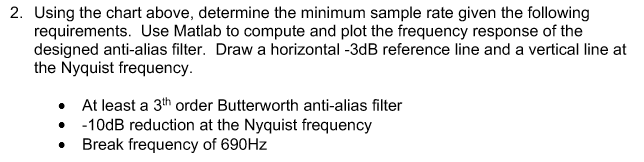

% Problem 2

% Building the Anti Alias Filter
dB_red = -10; % 10 dB reduction
fs = 2e3;     % Hz Sample Rate from the plot
N = 3; % 3rd Order

fbreak = 690; % Break frequency 
wbreak = 2*pi*fbreak;

fprintf(' Minimum anti-alias filter sample rate: %3.0f Hz ', fs);

 Minimum anti-alias filter sample rate: 2000 Hz 

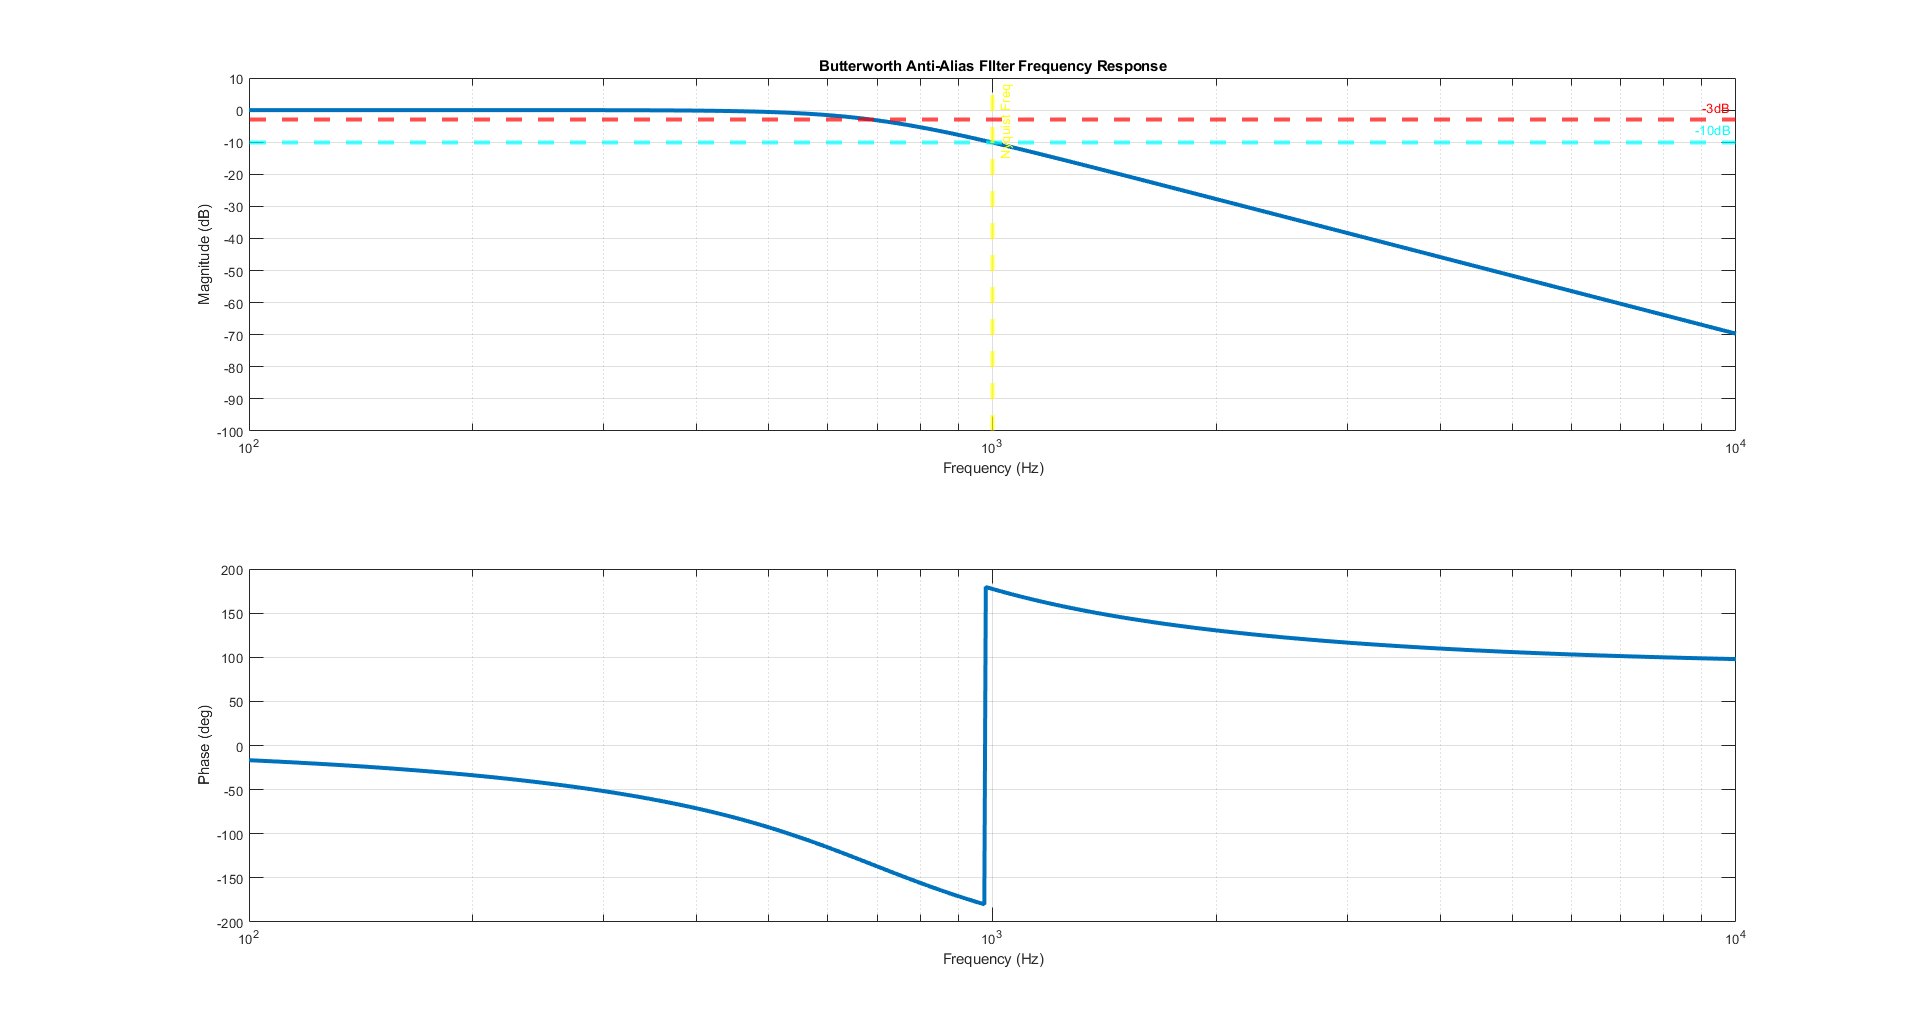


[num, den] = butter(N, wbreak, 's');

fr = logspace(2, 4, 1000);
P2_frf = freqs(num, den, 2*pi*fr);

Magnitude = abs(P2_frf);
Phase_deg = (180/pi)*angle(P2_frf);


figure()
% Magnitude Plot
subplot(2,1,1)
semilogx(fr, 20*log10(Magnitude), 'LineWidth', 3);
grid on
hold on
% xlim([100 1500]);
ylim([-100 10]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Butterworth Anti-Alias FIlter Frequency Response');

% -3dB Horizontal Reference line 
yline(-3, '--r', '-3dB', 'LineWidth', 3);

% -10dB Horizontal Reference line 
yline(-10, '--c', '-10dB', 'LineWidth', 3);

% Nyquist frequency Vertical Reference line
xline((2000)/2, '--y', 'Nyquist Freq', 'LineWidth', 3); % Because sample rate is 2kHz

% Phase Plot
subplot(2,1,2)
semilogx(fr, Phase_deg, 'LineWidth', 3);
grid on
xlabel('Frequency (Hz)');
ylabel('Phase (deg)');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

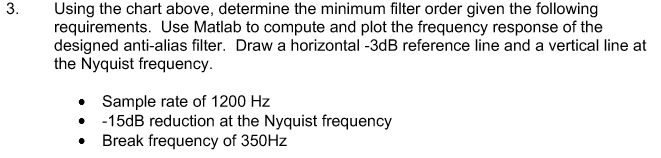

% Problem 3

% Building the Anti Alias Filter
dB_red = -15; % 15 dB reduction
fs = 1.2e3;     % Hz Sample Rate 

fbreak = 350; % Break frequency 
wbreak = 2*pi*fbreak;

[num2, den2] = butter(2, wbreak, 's');
[num3, den3] = butter(3, wbreak, 's');
[num4, den4] = butter(4, wbreak, 's');

fr = logspace(2, 4, 1000);
P32_frf = freqs(num2, den2, 2*pi*fr);
P33_frf = freqs(num3, den3, 2*pi*fr);
P34_frf = freqs(num4, den4, 2*pi*fr);
P3_frf = [P32_frf; P33_frf; P34_frf];

Magnitude = abs(P3_frf);
Phase_deg = (180/pi)*angle(P3_frf);


figure()
% Magnitude Plot
subplot(2,1,1)
semilogx(fr, 20*log10(Magnitude), 'LineWidth', 3);
grid on
hold on
% xlim([100 1500]);
ylim([-100 10]);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Butterworth Anti-Alias FIlter Frequency Response');

% -3dB Horizontal Reference line 
yline(-3, '--r', '-3dB', 'LineWidth', 3);

% -15dB Horizontal Reference line 
yline(-15, '--c', '-15dB', 'LineWidth', 3);

% Nyquist frequency Vertical Reference line
xline((fs)/2, '--y', 'Nyquist Freq', 'LineWidth', 3); % Because sample rate is 2kHz

% Phase Plot
subplot(2,1,2)
semilogx(fr, Phase_deg, 'LineWidth', 3);
grid on
xlabel('Frequency (Hz)');
ylabel('Phase (deg)');
legend('2nd Order', '3rd Order', '4th Order');

fprintf(' Minimum filter order from graph: 3 ');

 Minimum afilter order from graph: 3rd 

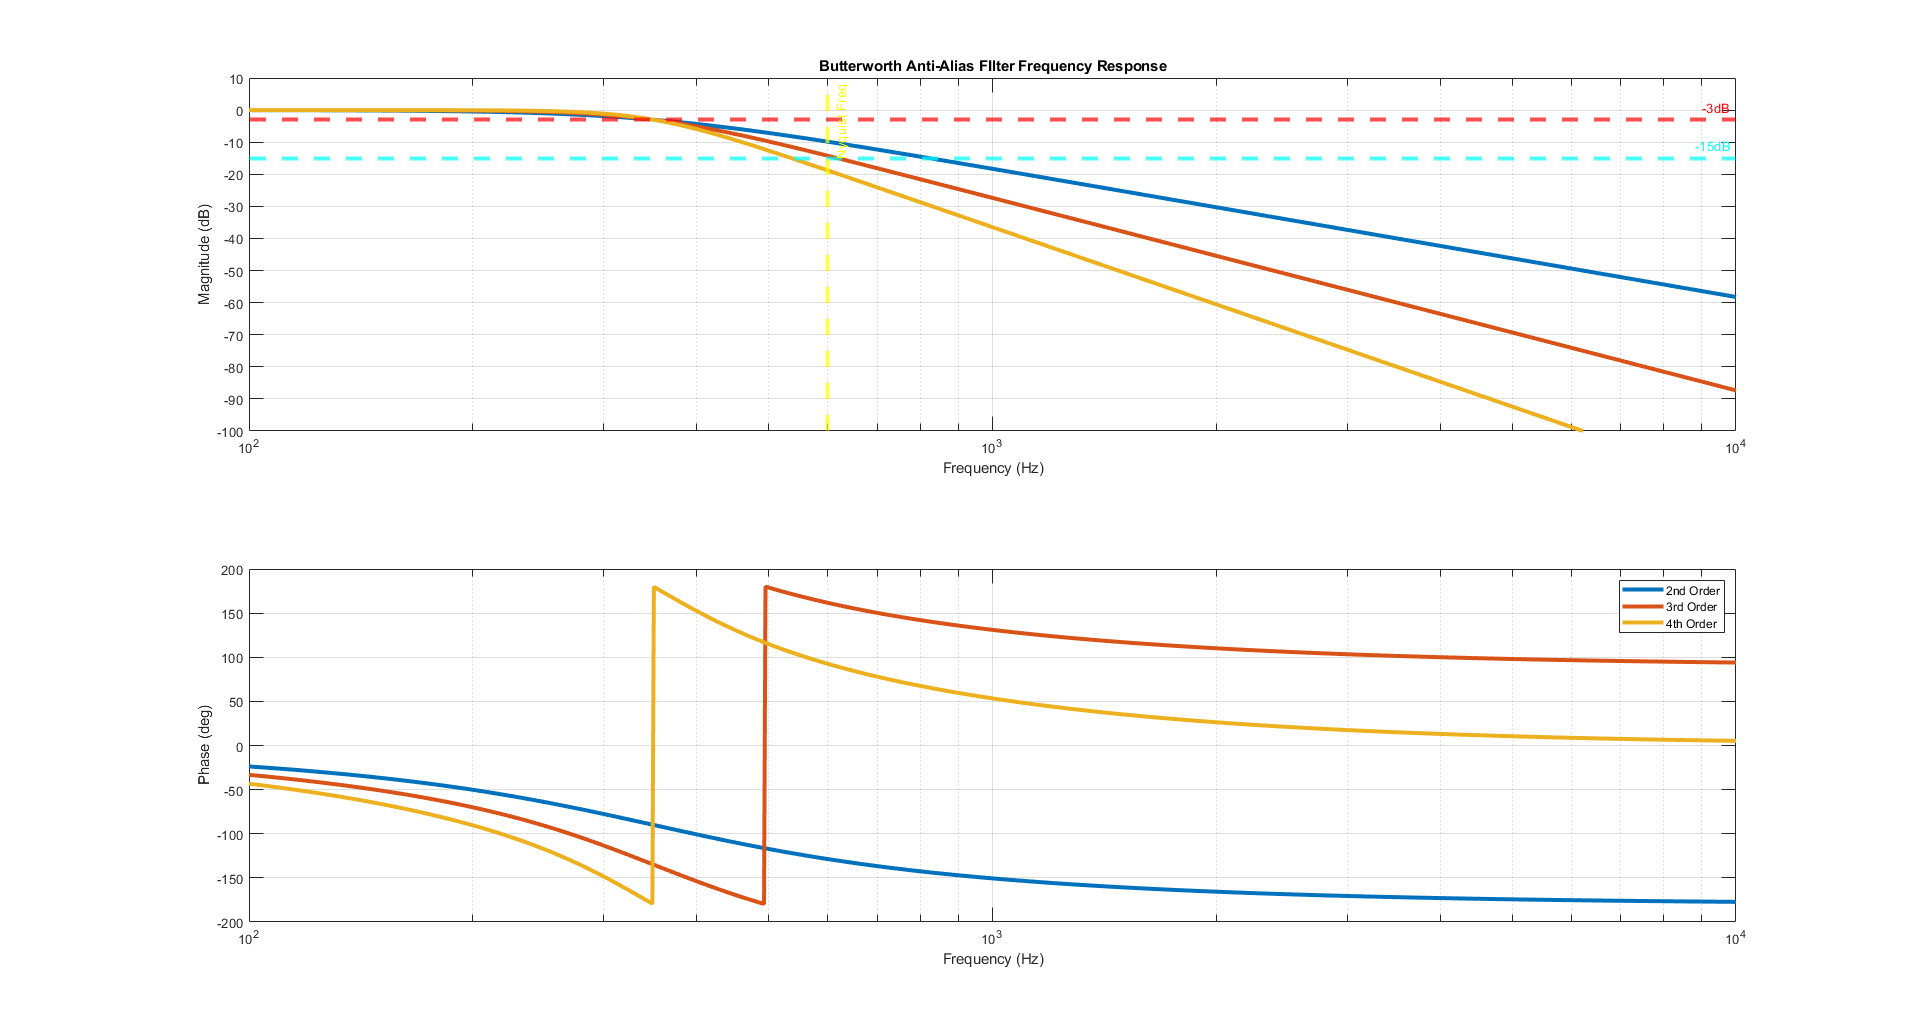


% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

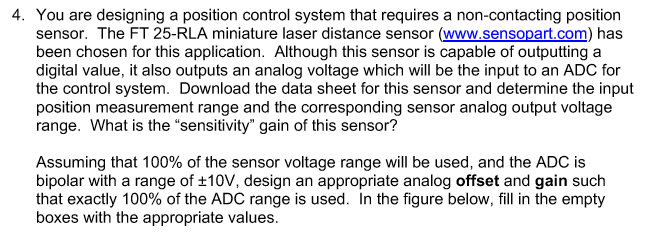

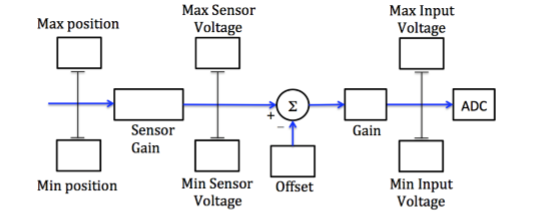

## **Solution:**

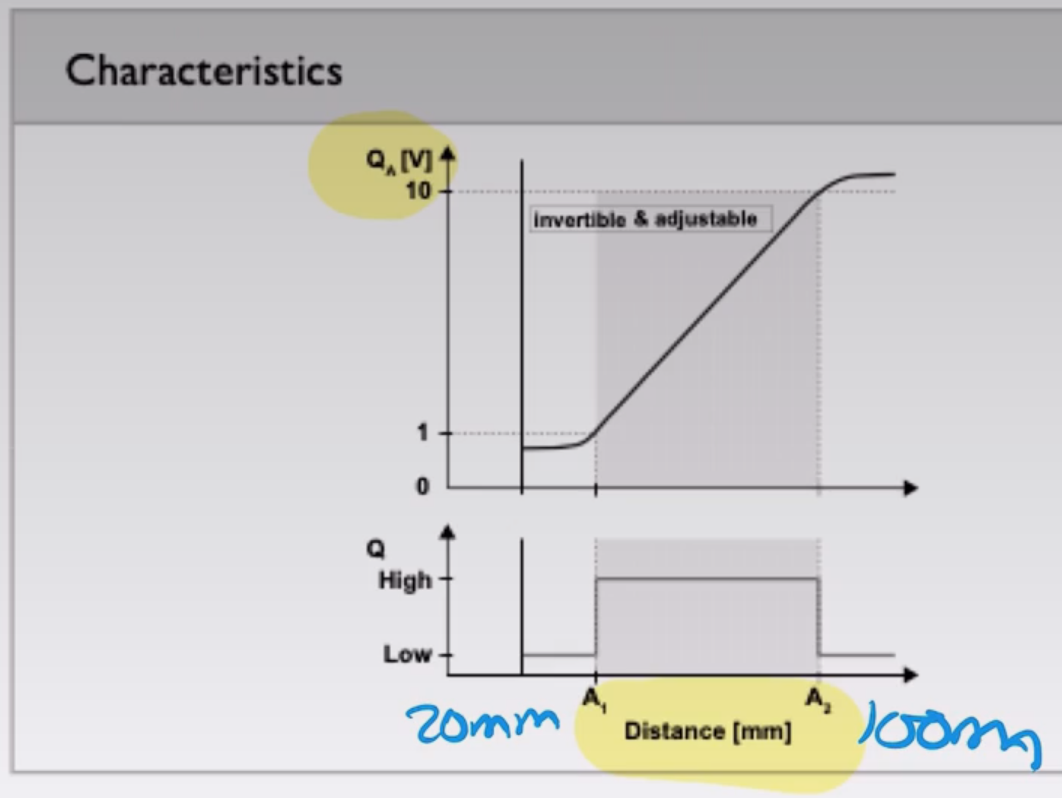

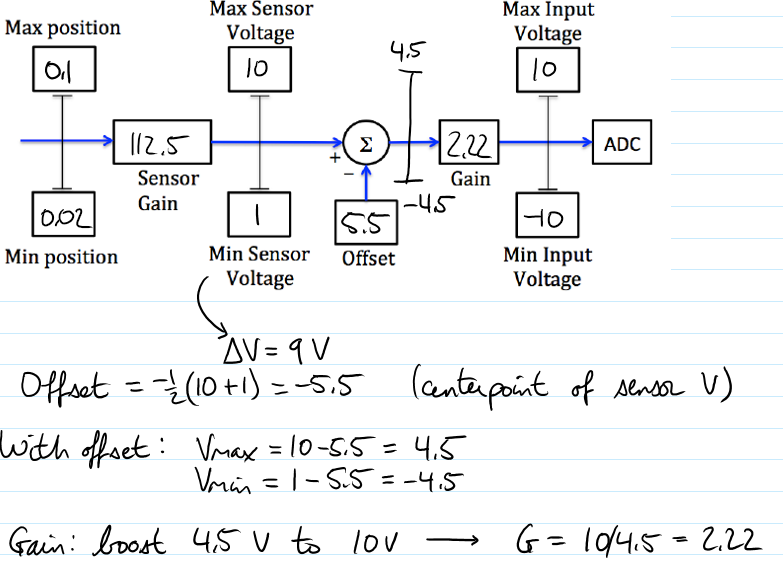

% Problem 4

% Datasheet link: https://www.sensopart.com/jdownloads/Produktdetails/FT_25-RLA_e.pdf

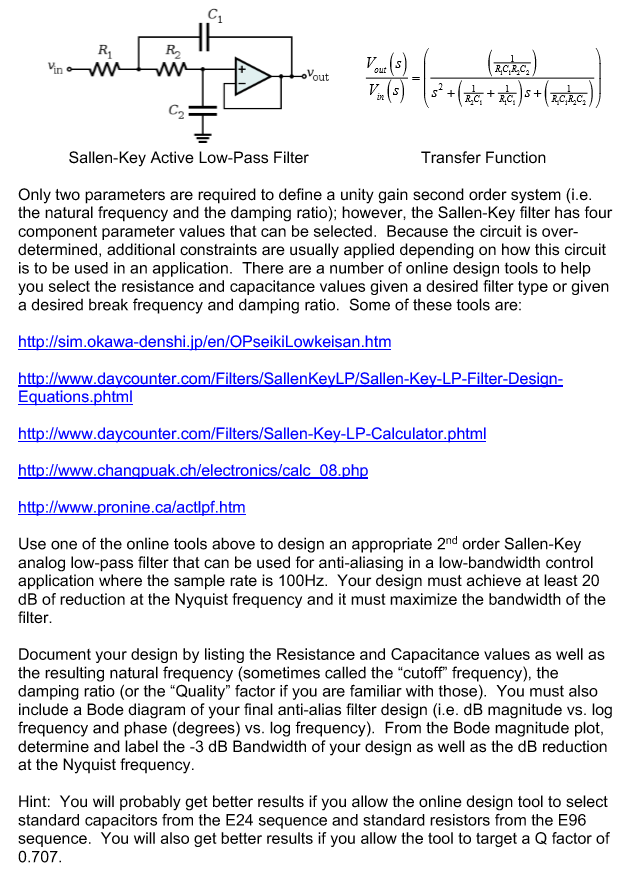

**Using the following parameters**:

Capacitors -> E24 Sequence

Resistors -> E96 Sequence

Q factor = 0.707 $\Longrightarrow \;$$Q=\frac{1}{2*\zeta }$    Therefore, $\zeta$(Damping ratio) = 0.707

**Note:** Cutoff Frequency = $\frac{1}{2*\Pi *\sqrt{R_1 *R_2 *C_1 *C_2 }}$

Desired break frequency = Cutoff Frequency = 15.83 Hz (Found Above)

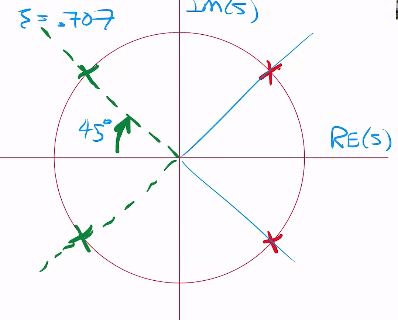

## **Solution**:

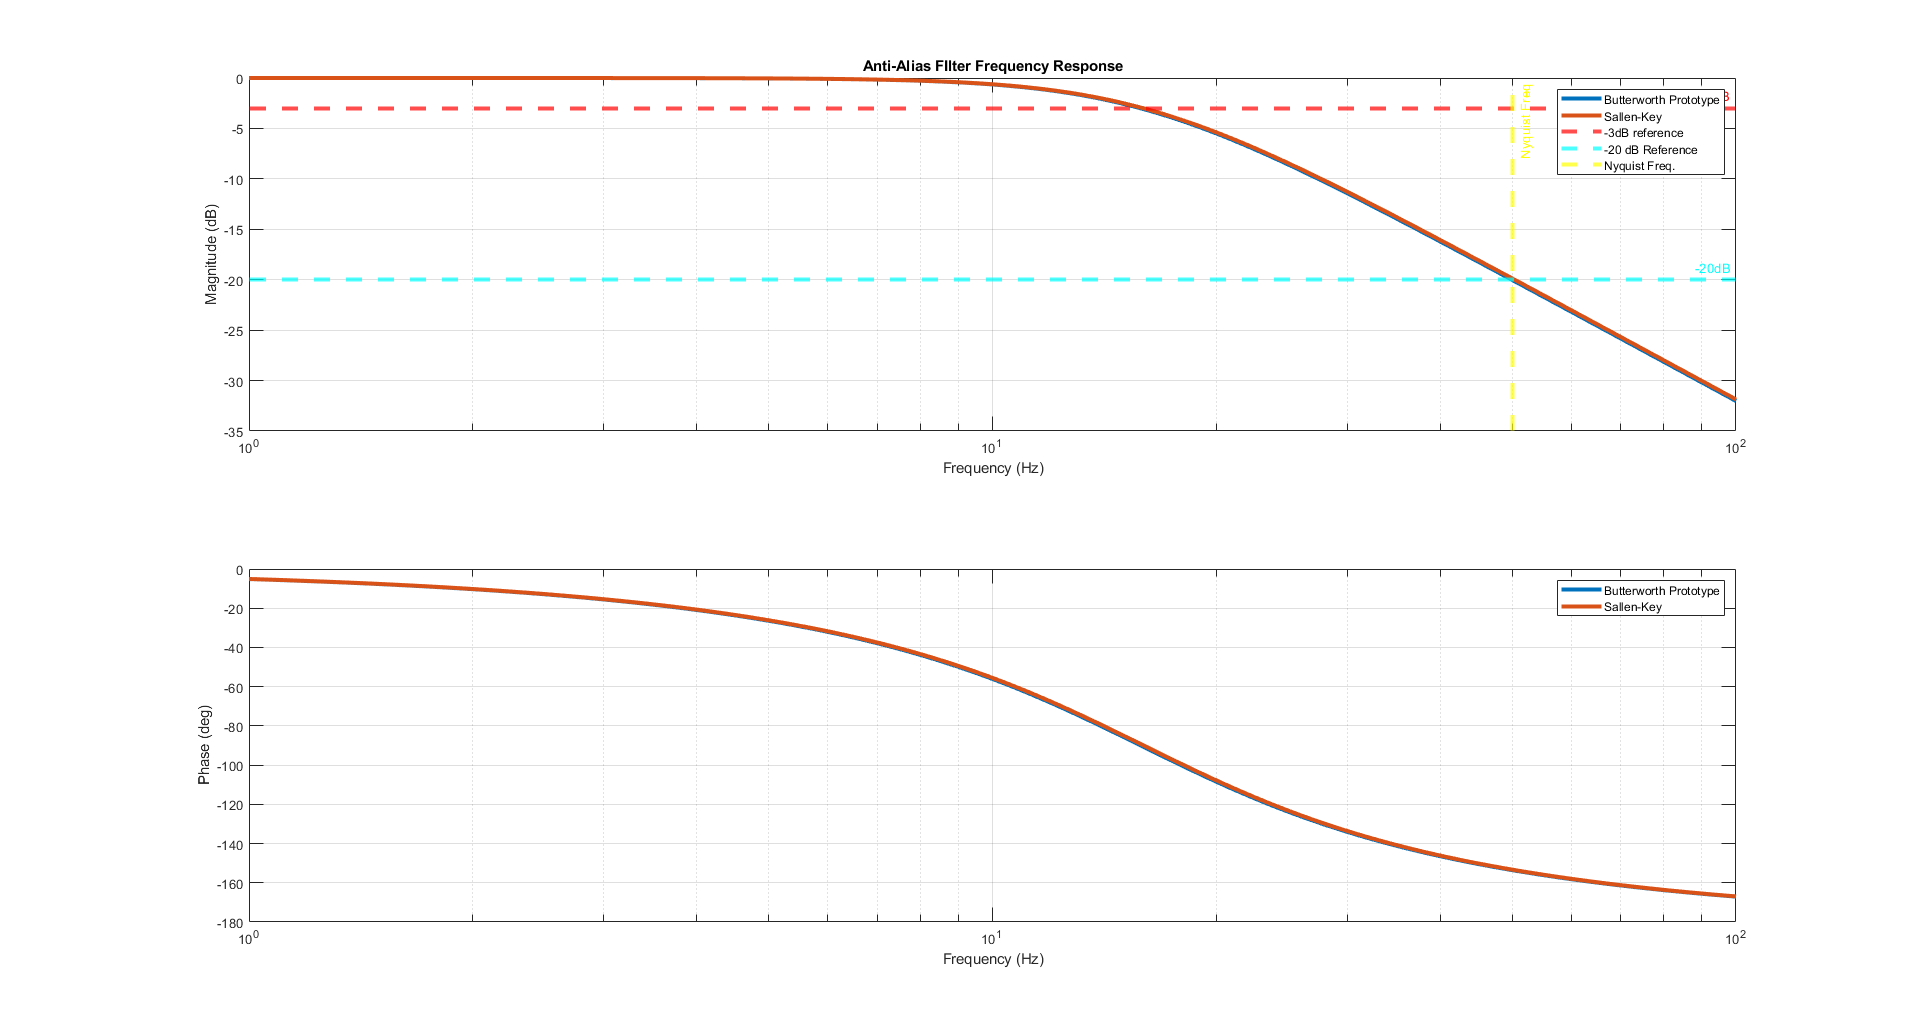

% Problem 5

% Prototyping Butterworth  to get
fr = logspace(0, 2, 1000);
dB_red = -20;
fbreak = 15.83;
fs = 100; % Hz

[numb, denb] = butter(2, 2*pi*fbreak, 's'); % 2nd order filter

AAb = freqs(numb, denb, 2*pi*fr);

Magnitude = abs(AAb);
Phase_deg = (180/pi)*angle(AAb);

% For Sallen-Key
R1 = 18700; % Ohms
R2 = 11300; % Ohms
C1 = 1e-6; % F
C2 = 0.47e-6; % F
zeta = 0.707; % Damping Ratio

% Building the Anti Alias Filter
s = tf('s');
cutoff_frequency5 = 1/(2*pi*sqrt(R1*R2*C1*C2));
transfer_function5 = ((2*pi*cutoff_frequency5)^2)/(s^2 + s*2*zeta*((2*pi*cutoff_frequency5))  + ((2*pi*cutoff_frequency5)^2));
minimum_samplerate5 = 100; % Hz

% Simulating the Frequency Response of the Sallen-Key filter
magnitude6 = abs(squeeze(freqresp(transfer_function5, 2*pi*fr)));
Phase6 = (180/pi)*angle(squeeze(freqresp(transfer_function5, 2*pi*fr)));



% Plotting Both Butterworth and Sallen-Key filter
figure()
% Magnitude Plot
subplot(2,1,1)
semilogx(fr, 20*log10(Magnitude), 'LineWidth', 3);
grid on
hold on
semilogx(fr, 20*log10(magnitude6), 'LineWidth', 3);
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Anti-Alias FIlter Frequency Response');
xlim([1 100]);

% -3dB Horizontal Reference line 
yline(-3, '--r', '-3dB', 'LineWidth', 3);

% -20dB Horizontal Reference line 
yline(-20, '--c', '-20dB', 'LineWidth', 3);

% Nyquist frequency Vertical Reference line
xline((fs)/2, '--y', 'Nyquist Freq', 'LineWidth', 3); % Because sample rate is 2kHz

legend('Butterworth Prototype', 'Sallen-Key', '-3dB reference', '-20 dB Reference', 'Nyquist Freq.');


% Phase Plot
subplot(2,1,2)
semilogx(fr, Phase_deg, 'LineWidth', 3);
grid on
hold on
semilogx(fr, Phase6, 'LineWidth', 3);
xlabel('Frequency (Hz)');
ylabel('Phase (deg)');
legend('Butterworth Prototype', 'Sallen-Key');


% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

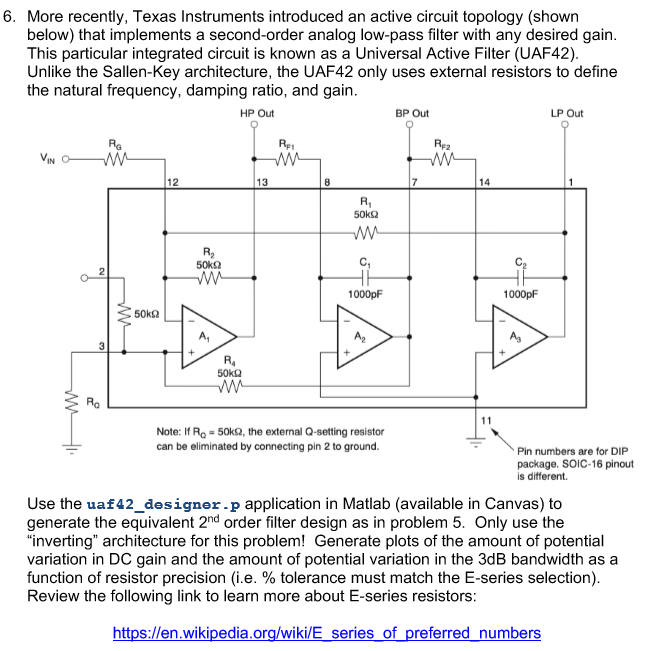

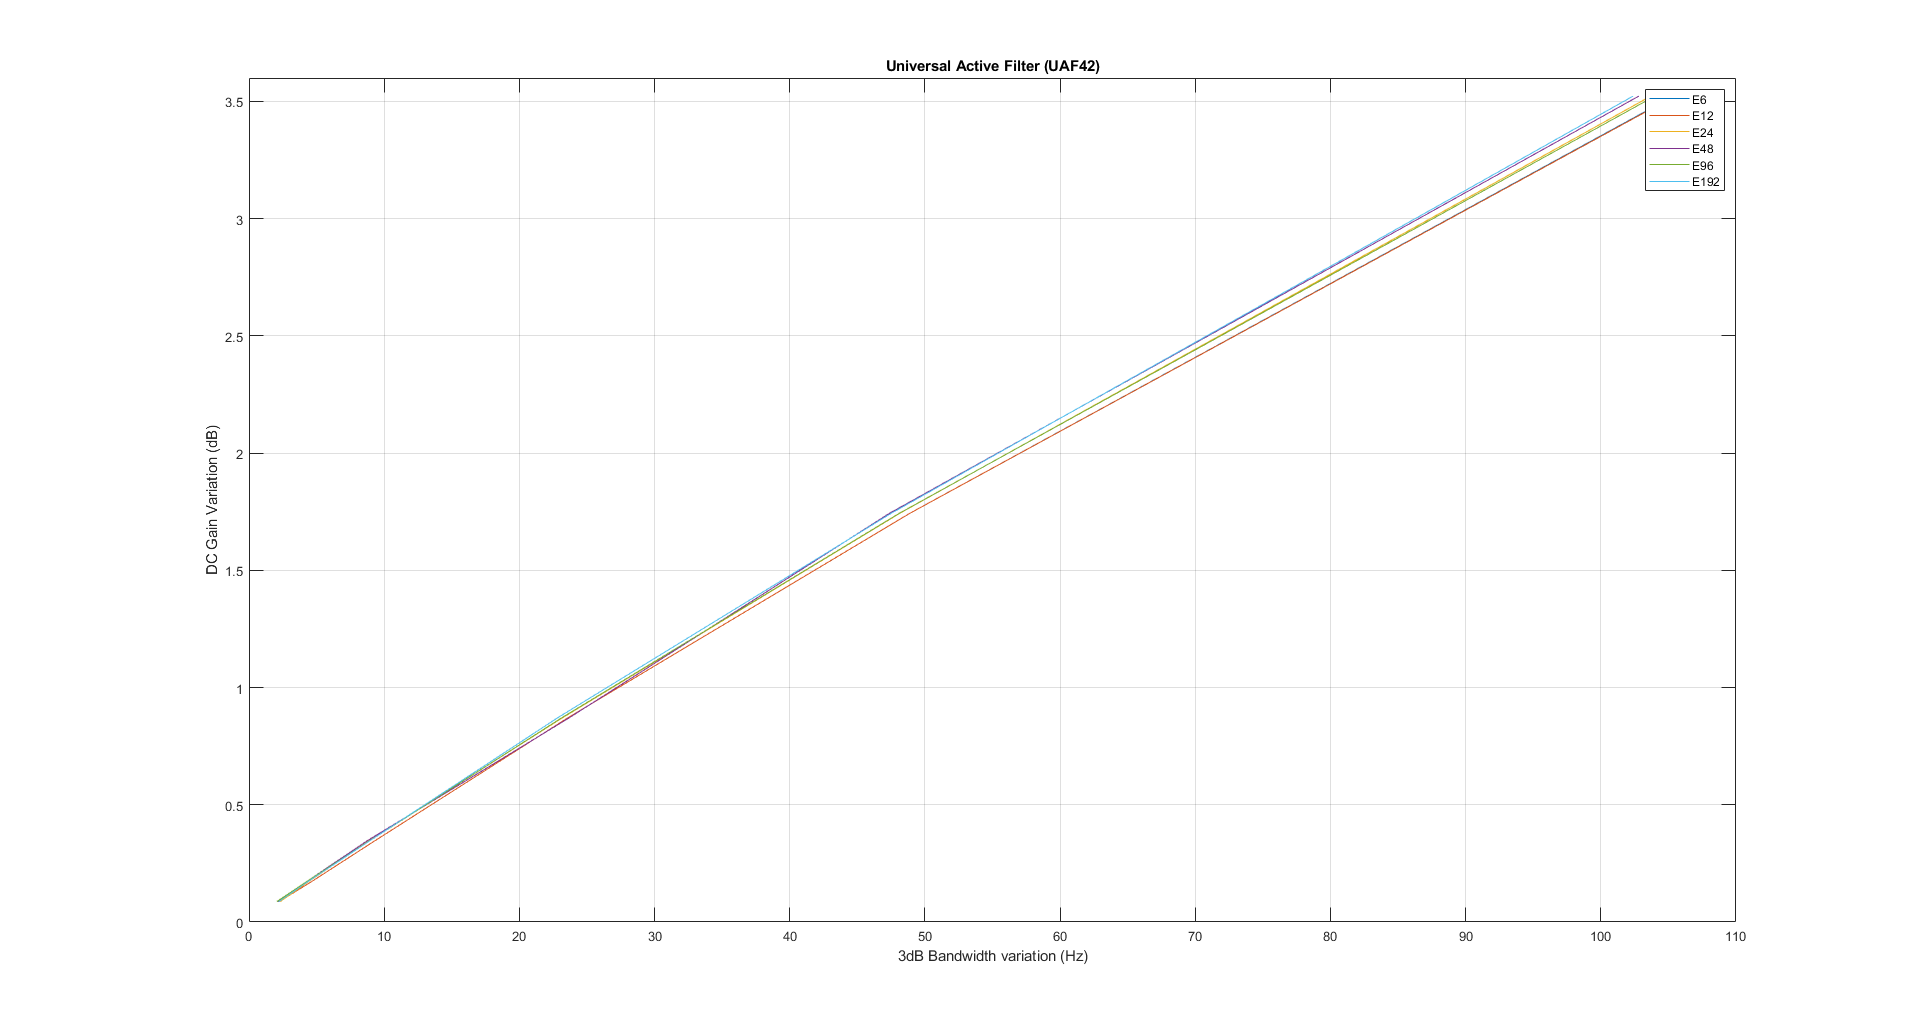

% Problem 6

% For E6
y1 = [0.0868793, 0.173763, 0.347561, 0.869511, 1.7434, 3.52262]; % dB
x1 = [2.23049, 4.66403, 9.33875, 23.5443, 48.8885, 105.368]; % Hz

y2 = [0.0868793, 0.173763, 0.347567, 0.869511, 1.7434, 3.52]; % dB
x2 = [2.23049, 4.66403, 9.33875, 23.5443, 48.888, 105.37]; % Hz

y3 = [0.086881, 0.173766, 0.347567, 0.869527, 1.74343, 3.52268]; % dB
x3 = [2.30857, 4.43984, 8.87387, 23.148, 48.1465, 103.696]; % Hz

y4 = [0.0868808, 0.173766, 0.347566, 0.869525, 1.74343, 3.52267]; % dB
x4 = [2.14872, 4.29771, 8.76867, 23.6456, 47.3779, 102.807]; % Hz

y5 = [0.08688, 0.173764, 0.347563, 0.869517, 1.74341, 3.52264]; % dB
x5 = [2.05302, 4.29293, 8.95316, 23.0865, 48.107, 103.991]; % Hz

y6 = [0.0868807, 0.173766, 0.347566, 0.869525, 1.74343, 3.52267]; % dB
x6 = [2.19676, 4.39378, 8.96469, 22.7856, 47.5101, 102.381]; % Hz

figure()
plot(x1 , y1);
hold on
grid on
plot(x2 , y2);
plot(x3 , y3);
plot(x4 , y4);
plot(x5 , y5);
plot(x6 , y6);
hold off
xlim([0 110]);
ylim([0 3.6]);
legend('E6', 'E12', 'E24', 'E48', 'E96', 'E192');
xlabel('3dB Bandwidth variation (Hz)');
ylabel('DC Gain Variation (dB)');
title('Universal Active Filter (UAF42)');

% In order to maximize the figure window in Windows
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);


% uaf42_designer();
